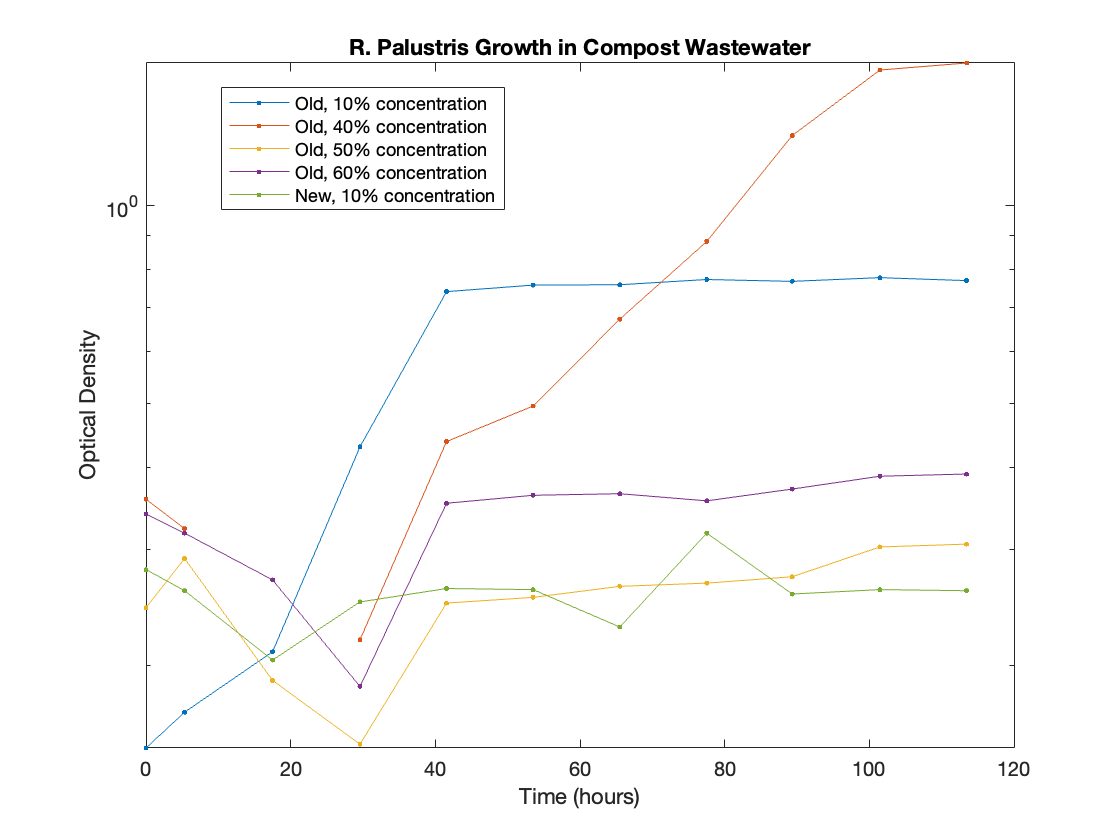

clear
clf

data = readmatrix('rpalus_data_02222023.csv');

% label data from csv
time = data(:, 1) / 60;     % hours
old_10percent = data(:, 2); % optical density
old_40percent = data(:, 3); % optical density
old_50percent = data(:, 4); % optical density
old_60percent = data(:, 5); % optical density
new_10percent = data(:, 6); % optical density

% Plot
figure(1)
semilogy(time, old_10percent, '.-');
hold on
semilogy(time, old_40percent, '.-');
semilogy(time, old_50percent, '.-');
semilogy(time, old_60percent, '.-');
semilogy(time, new_10percent, '.-');
title("R. Palustris Growth in Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Old, 10% concentration", "Old, 40% concentration", "Old, 50% concentration", ...
       "Old, 60% concentration", "New, 10% concentration", 'location', 'best')
hold off

## Analysis

### Old, 10%

We isolated the exponential section of the 40% curve, which happens between the 3rd and 5th data point.

figure(2)
isolate_10 = 3:5;
time_10 = time(isolate_10);
old_10percentfit = old_10percent(isolate_10);

We can now use the `fit` function to get an exponential fit.

[fitobject_old10,gof_old10] = fit(time_10,old_10percentfit,'exp1')

fitobject_old10 =      General model Exp1:
     fitobject_old10(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.09516  (-0.08572, 0.276)
       b =     0.04953  (-0.0004514, 0.09951)

gof_old10 = struct with fields:
           sse: 6.2228e-04
       rsquare: 0.9956
           dfe: 1
    adjrsquare: 0.9912
          rmse: 0.0249


The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 09516*e^{0\ldotp 04953x}$$


with an r squared value is 0.9956. We can plot this fit over the original data.

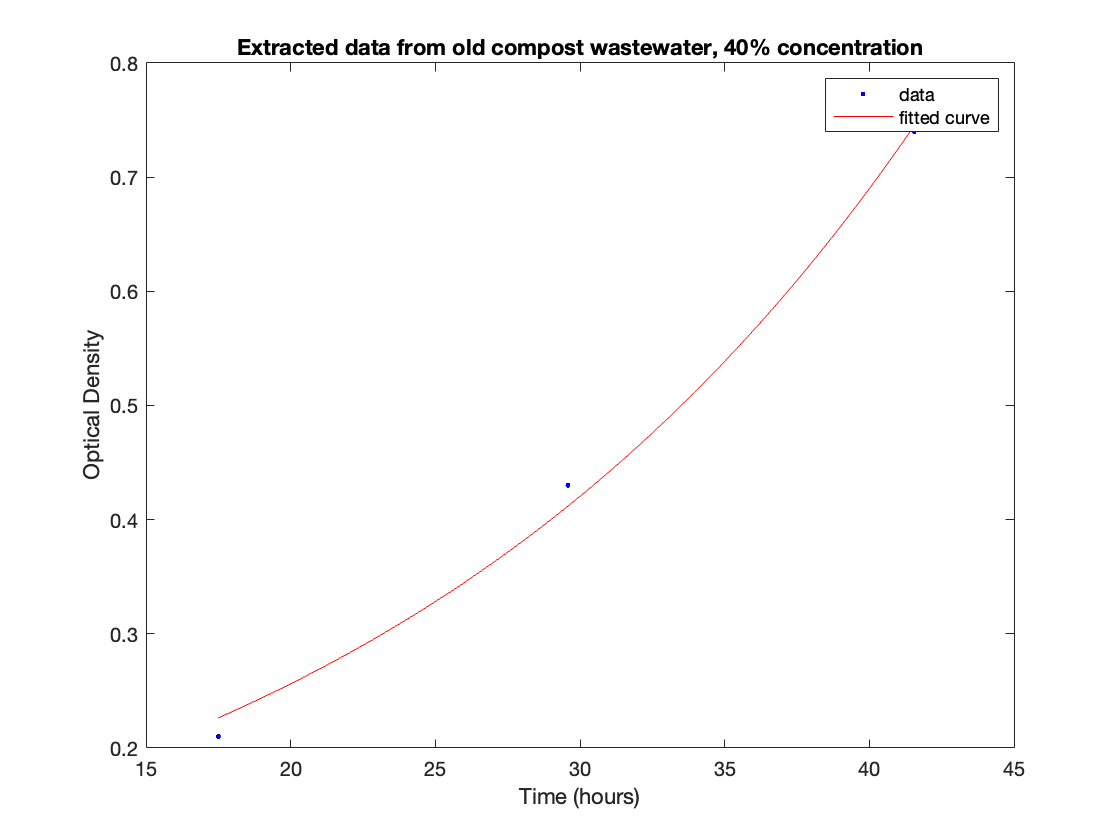

plot(fitobject_old10, time_10, old_10percentfit)
title('Extracted data from old compost wastewater, 10% concentration')
xlabel('Time (hours)')
ylabel('Optical Density')

### Old, 40%

We isolated the exponential section of the 40% curve, which happens between the 4th and 10th data point.

figure(2)
isolate_40 = 4:10;
time_40 = time(isolate_40);
old_40percentfit = old_40percent(isolate_40);

We can now use the `fit` function to get an exponential fit.

[fitobject,gof] = fit(time_40,old_40percentfit,'exp1')

fitobject =      General model Exp1:
     fitobject(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1368  (0.0975, 0.176)
       b =     0.02445  (0.02124, 0.02766)

gof = struct with fields:
           sse: 0.0132
       rsquare: 0.9910
           dfe: 5
    adjrsquare: 0.9892
          rmse: 0.0514


The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 1368*e^{0\ldotp 02445x}$$


with an r squared value is 0.9910. We can plot this fit over the original data.

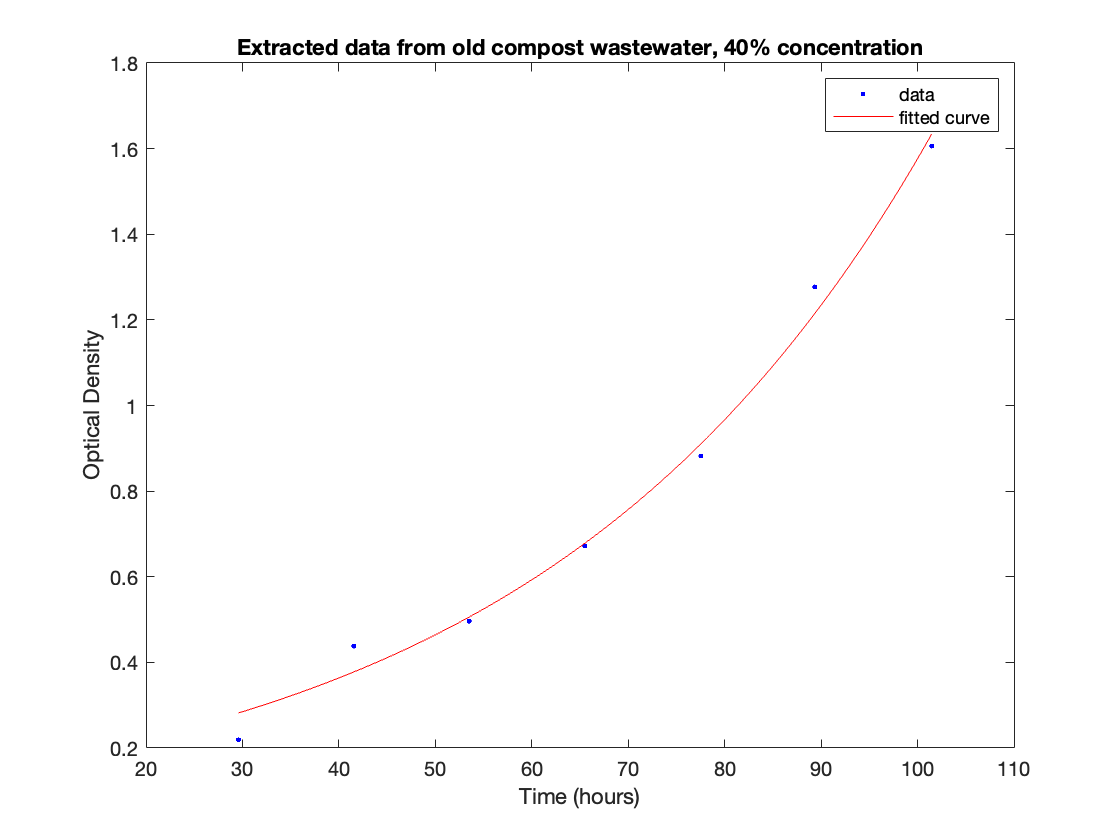

plot(fitobject, time_40, old_40percentfit)
title('Extracted data from old compost wastewater, 40% concentration')
xlabel('Time (hours)')
ylabel('Optical Density')